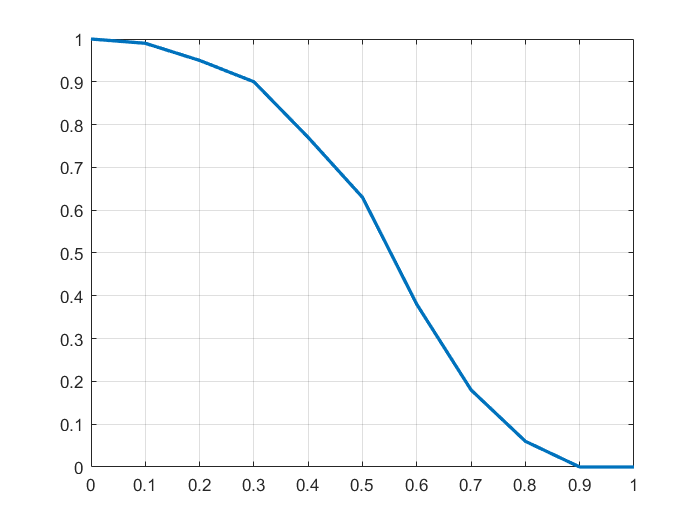

clearvars;
load Hmatrix3.mat
p=0:0.1:1;
Nsim=100;
col=width(H);
row=height(H);

code=zeros(1,col);  
nsuc=zeros(1,length(p));   
cnt=1; 
for p1=p
    for b=1:Nsim
        noise=rand(1,col)<p1;
        Msg_received1=code-noise;
        llr=zeros(1,col);
         for i=1:col
            if Msg_received1(i)==1
                llr(i)=log(0/1);
            elseif(Msg_received1(i)==0)
                llr(i)=log(1/0);
            else
                llr(i)=0;
            end
        end
        
        Mij=zeros(row,col);
        Mij=Mij-1;
        for i=1:row
            for j=1:col
                if H(i,j)==1
                    Mij(i,j)=llr(j);
                end
            end
        end
        
        Eij=zeros(row,col);
        for i=1:row
            for j=1:col
                if Mij(i,j)~=-1
                    temp_cnt=1;
                    not_ii=j;
                    for ii=1:col
                        if (ii~=not_ii) && (Mij(i,ii)~=-1)
                            Mj_I=Mij(i,ii);
                            temp_cnt=temp_cnt * tanh(Mj_I/2);
                        end
                    end         
                    Eij(i,j)=log((1+temp_cnt)/(1-temp_cnt));
                end
            end
        end
        
        Li=zeros(1,col);
        for i=1:col
            onlylj=sum(Eij(:,i))+llr(i);
            Li(i)=onlylj;
        end
        
        Msg_received=zeros(1,col);
        for i=1:col
           if Li(i)==-Inf
                        Msg_received(i)=1;
                    elseif(Li(i)==Inf)
                        Msg_received(i)=0;
                    else
                        Msg_received(i)=-1;
           end
        end
        
        if(sum(Msg_received)==0)
            nsuc(cnt)=nsuc(cnt)+1;
        else
            for iit=1:50
                Mji=zeros(row,col);
                Mji=Mji-1;
                for i=1:row
                    for j=1:col
                        if H(i,j)==1
                            temp_cnt=0;
                            not_ii=i;
                            for ii=1:row
                                if (Eij(ii,j)~=0) && (ii~=not_ii)
                                    temp_cnt=temp_cnt+Eij(ii,j);
                                end
                            end                          
                            Mji(i,j)=temp_cnt+llr(j);
                        end
                    end
                end
                
                Eij=zeros(row,col);
                for i=1:row
                    for j=1:col
                        if Mji(i,j)~=-1
                            temp_cnt=1;
                            not_ii=j;
                            for ii=1:col
                                if (ii~=not_ii) && (Mji(i,ii)~=-1)
                                    Mj_I=Mji(i,ii);
                                    temp_cnt=temp_cnt * tanh(Mj_I/2);
                                end
                            end                           
                            Eij(i,j)=log((1+temp_cnt)/(1-temp_cnt)); 
                        end
                    end
                end
                
                Li=zeros(1,col);
                for i=1:col                
                    Li(i)=sum(Eij(:,i))+llr(i);
                end
                
                Msg_received=zeros(1,col);
                for i=1:col
                    if Li(i)==-Inf
                        Msg_received(i)=1;
                    elseif(Li(i)==Inf)
                        Msg_received(i)=0;
                    else
                        Msg_received(i)=-1;
                    end
                end
                
                if(sum(Msg_received)==0)
                    nsuc(cnt)=nsuc(cnt)+1;
                    break;
                end
            end
        end
    end
    cnt=cnt+1;
end

plot(p,nsuc/Nsim,"LineWidth",2);
grid on;